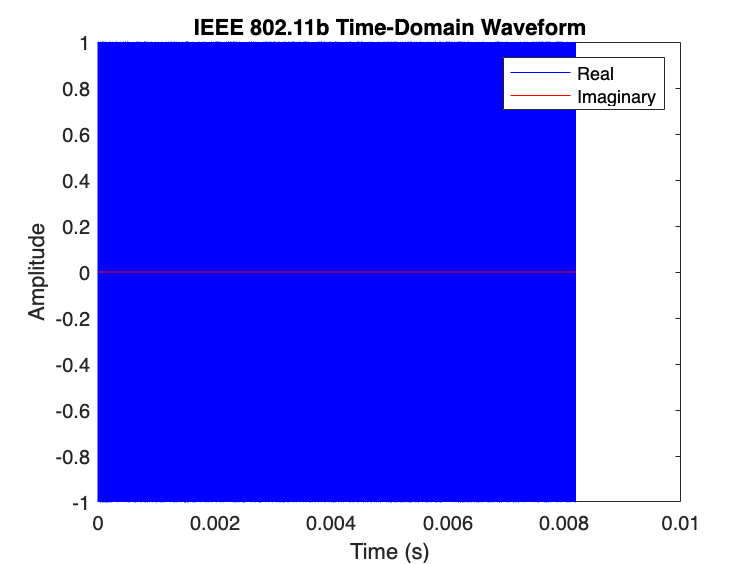

load('test1.mat');

% Extract relevant information
waveform = waveStruct.waveform;
Fs = waveStruct.Fs;

% Plot the time-domain waveform
time = (0:length(waveform)-1) / Fs;
figure;
plot(time, real(waveform), 'b', time, imag(waveform), 'r');
title('IEEE 802.11b Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Real', 'Imaginary');

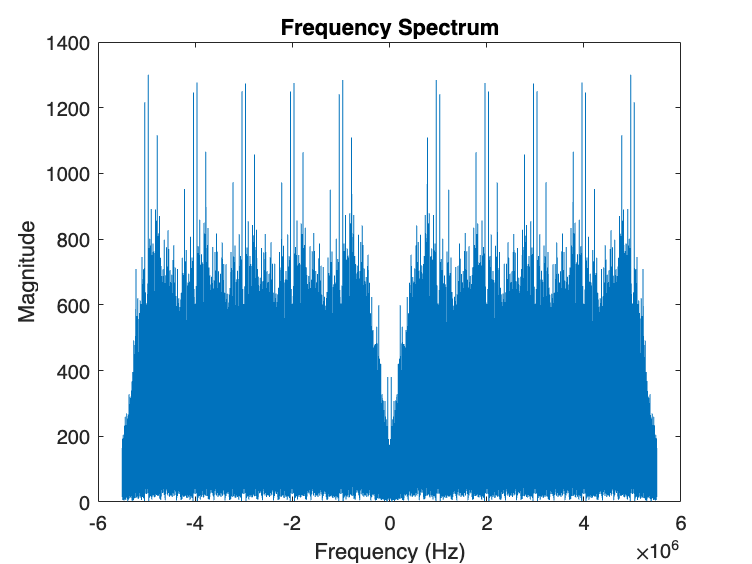


% Compute and plot the frequency-domain spectrum
spectrum = fftshift(fft(waveform));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

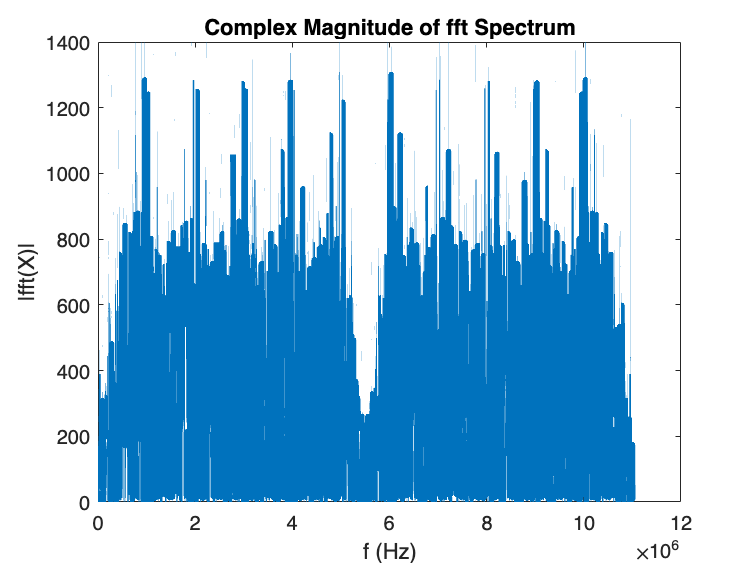


t = time;
L = length(waveform);
Y = fft(waveform);
plot(Fs/L*(0:L-1),abs(Y),"LineWidth",3)
title("Complex Magnitude of fft Spectrum")
xlabel("f (Hz)")
ylabel("|fft(X)|")

## try to run through low pass


top_end = 5044000

top_end = 5044000

low_waveform = lowpass(waveform,top_end,Fs);
%low_waveform = waveform;
%low_end = 2978000
%low_waveform = highpass(low_waveform,low_end,Fs);


## frequency shift up 1.22 MHz

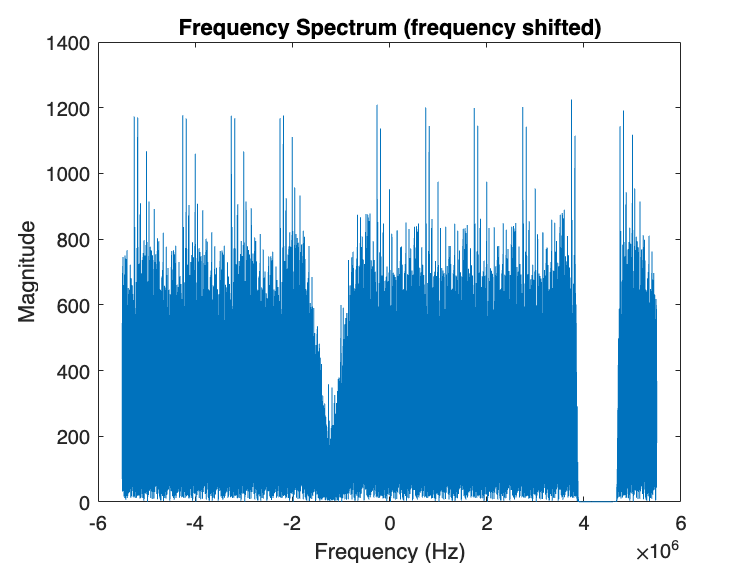

t = time;
frequency_offset = -1.22e6;
shifter = exp(1i * 2 * pi * frequency_offset * t);
shifter = shifter.';
shifted_signal = low_waveform .* shifter;

spectrum = fftshift(fft(shifted_signal));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum (frequency shifted)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');



top_end = 1044000

top_end = 1044000

shifted_signal = lowpass(shifted_signal,top_end,Fs);
shifter = [];


## graph results

disp("hi");

hi


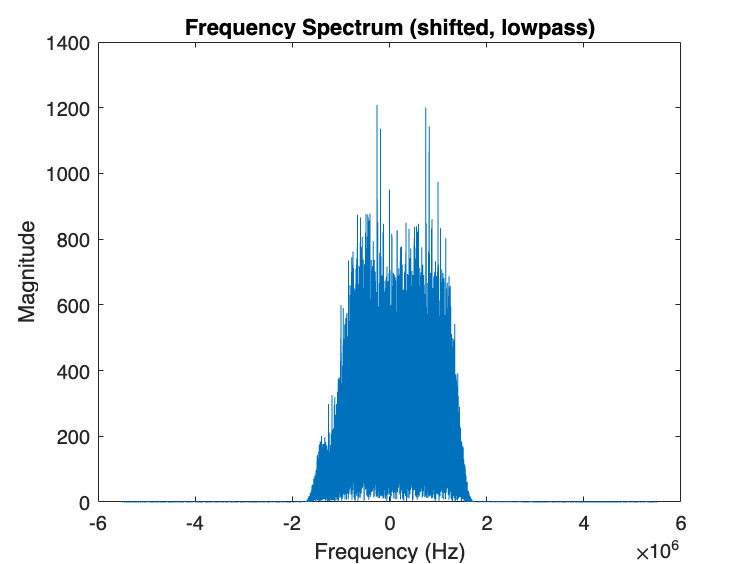


%specAnal = spectrumAnalyzer(SampleRate=11e6);
%specAnal(shifted_signal)

%symbol_rate = 1e6;
%freq_sep = symbol_rate / 4  ;
%modulation_order = 2; % Binary FSK
%nsamp = 2;
%data_demod = fskdemod(modulated_signal, modulation_order, freq_sep, nsamp, symbol_rate);


spectrum = fftshift(fft(shifted_signal));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum (shifted, lowpass)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');



modulation_order = 2; % Binary FSK
nsamp = 11; % Number of samples per symbol (adjusted to an integer greater than 1)
symbol_rate = 11e6; % 1 MHz symbol rate Fs
Fs = symbol_rate

Fs = 11000000

freq_sep = symbol_rate / 11; 

data_demod = fskdemod(shifted_signal, modulation_order, freq_sep, nsamp, symbol_rate);



## descrambling

vectorLength = length(data_demod);

lastbyte = uint16(0);
bytemask = uint16(255);
dataout = zeros(length(data_demod));
output_strings = [];
for i = 1:8:vectorLength
    chunk = data_demod(i:min(i+8-1, vectorLength));
    strbyte = sprintf('%d', chunk);
    decbyte = bin2dec(strbyte);
    a = uint16(decbyte);

    reg = bitshift(a,8);
    reg = bitor(reg, lastbyte);

    % negative bitshift is right
    shift3 = bitshift(reg, -3);
    shift7 = bitshift(reg, -7);

    reg2 = bitxor(reg, shift3);
    reg2 = bitxor(reg2, shift7);

    descrambling_out = bitand(bytemask, reg2);
    output_string =  dec2bin(descrambling_out);
    if length(output_string) < 8
        leadingZeros = 8 - length(output_string);
        output_string = [repmat('0', 1, leadingZeros) output_string];
    end

    output_strings = [output_strings, output_string];
end

disp(length(output_strings));

        8192



disp(output_strings(67:73));

0101000


disp(output_strings(74:105));

10001001000001001000000000000000


## Graphing code


% Plot the time-domain waveform
%time = (0:length(low_waveform)-1) / Fs;
%figure;
%plot(time, real(low_waveform), 'b', time, imag(low_waveform), 'r');
%title('Time-Domain Waveform');
%xlabel('Time (s)');
%ylabel('Amplitude');
%legend('Real', 'Imaginary');

%
%
%
%
%
%
%

%smallw = waveform(1:length(waveform)/11/32,:);
%t = (0:length(smallw)-1) / Fs;
%instantaneous_phase = unwrap(angle(hilbert(smallw)));

% Compute the frequency deviation
%frequency_deviation = diff(instantaneous_phase) / (2 * pi * (t(2) - t(1)));

% Plot the waveform
%subplot(4, 1, 1);
%plot(t, smallw);
%title('Wireless Waveform');

% Plot the frequency deviation
%subplot(4, 1, 2);
%plot(t(2:end), frequency_deviation);
%title('Frequency Deviation');
%xlabel('Time');
%ylabel('Frequency Deviation');

% Display the plot
%sgtitle('Wireless Waveform and Frequency Deviation');

%backup_waveform = waveform;
%waveform = shifted_signal;

%smallw = waveform(1:length(waveform)/11/32,:);
%waveform = backup_waveform;
%t = (0:length(smallw)-1) / Fs;
%instantaneous_phase = unwrap(angle(hilbert(smallw)));

% Compute the frequency deviation
%frequency_deviation = diff(instantaneous_phase) / (2 * pi * (t(2) - t(1)));

% Plot the waveform
%figure;
%plot(t, smallw);
%title('Wireless Waveform');

%subplot(4, 1, 4);
%figure;
%plot(t(2:end), frequency_deviation);
%title('Frequency Deviation');
%xlabel('Time');
%ylabel('Frequency Deviation');
%sgtitle('Wireless Waveform and Frequency Deviation (filtered)');
